
clear;

csvFolderName = "RandomWalk";
clockTimeLimit = 30; % 体験時間 (s)
period = 3; % 歩行周期 (s)

legForwardTimeRate = 3; % 足スライダ前進 時間比
legBackwardTimeRate = 4; % 足スライダ後退 時間比

stockForwardTimeRate = 3; % ストックスライダ前進 時間比
stockBackwardTimeRate = 4; % ストックスライダ後退 時間比

upTimeRate = 1; % 伸縮 持ち上げ 時間比
downTimeRate = 1; % 伸縮 降下 時間比

stockFlyingTimeRate = 3; % ストック空中時間比
stockGroundTimeRate = 4; % ストック接地時間比

tiltBackwardTimeRate = stockForwardTimeRate;
tiltForwardTimeRate = stockBackwardTimeRate;

liftLength = 30; % 椅子 リフト長 単位 (mm)
pedalLength = 40; % ペダル長 単位 (mm)
seatSlideForwardLength = 100; % 椅子 スライド長 単位 (mm)
seatSlideBackwardLength = 50; % 椅子 スライド長 単位 (mm)
extendLength = 100; % 伸縮長 単位 (mm)
stockSlideForwardLength = 150; % ストック スライド前方向長 単位 (mm)
stockSlideBackwardLength = 100; % ストック スライド後方向長 単位 (mm)
tiltBackwardDeg = 5; % ストック 後傾角度 (deg)
tiltForwardDeg = -10; % ストック 前傾角度 (deg)

stockStartTime = 0;
waitTime = period/2;


stopTime = clockTimeLimit;
stopTable = table(stopTime);
writetable(stopTable, csvFolderName + '\' + "stop.csv");

randdt = 1.5;

椅子 リフト

L = liftLength; % スライド長 単位 (mm)
clockTime = 0;
deltaTime = rand + randdt;
while clockTime(end,1) < clockTimeLimit - 2
    clockTime(end+1,1) = clockTime(end,1) + deltaTime(end,1);
    deltaTime(end+1,1) = rand + randdt;
end

absolutePosition = L*rand(size(clockTime));
useStiffness = zeros(size(clockTime));

lifter = table(clockTime, deltaTime, absolutePosition, useStiffness)

lifter = 15×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

          0        1.713           6.3873              0      
      1.713       1.8192           20.165              0      
     3.5322       2.0065           3.4562              0      
     5.5387       1.9753           28.778              0      
      7.514       2.2109           11.088              0      
     9.7248       2.1762           25.961              0      
     11.901       1.6292           7.6411              0      
      13.53        2.251           3.9888              0      
     15.781       2.4577           4.4838              0      
     18.239       2.2366           3.0372              0      
     20.476       2.0747            4.251              0      
      22.55       1.7554           11.146              0      
     24.306       2.1828           20.153              0      
     26.489       1.8342          

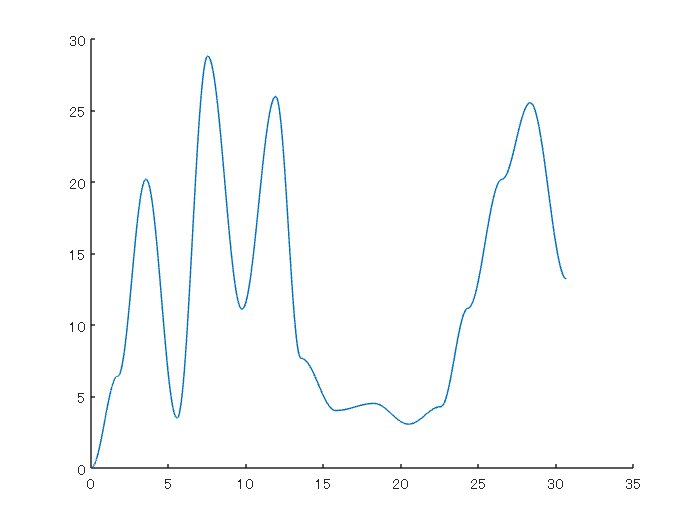

writetable(lifter, csvFolderName + '\' + "lifter.csv");
figure;
[lifter_x, lifter_t] = showGraph(clockTime, deltaTime, absolutePosition);

左ペダル

L = pedalLength; % スライド長 単位 (mm)
clockTime = 0;
deltaTime = rand + randdt;
while clockTime(end,1) < clockTimeLimit - 2
    clockTime(end+1,1) = clockTime(end,1) + deltaTime(end,1);
    deltaTime(end+1,1) = rand + randdt;
end

absolutePosition = L*rand(size(clockTime));
useStiffness = zeros(size(clockTime));

leftPedal = table(clockTime, deltaTime, absolutePosition, useStiffness)

leftPedal = 16×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

          0       1.5535              34.9             0      
     1.5535       2.2391            29.451             0      
     3.7927       2.1111            20.676             0      
     5.9037       1.5136            39.347             0      
     7.4174       1.7809            21.663             0      
     9.1983       2.1584            8.4024             0      
     11.357       2.1835            37.532             0      
      13.54        2.355            26.367             0      
     15.895       1.8846            10.102             0      
      17.78       1.7292            8.3564             0      
     19.509       1.5525            27.421             0      
     21.062       2.2047            12.947             0      
     23.266       1.6784            2.0873             0      
     24.945       2.3891       

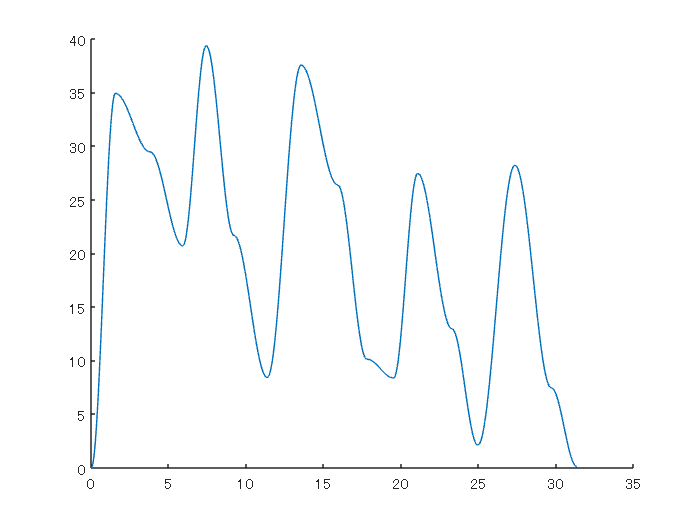

writetable(leftPedal, csvFolderName + '\' + "leftPedal.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
figure;
[leftPedal_x, leftPedal_t] = showGraph(clockTime, deltaTime, absolutePosition);

右ペダル

L = pedalLength; % スライド長 単位 (mm)
clockTime = 0;
deltaTime = rand + randdt;
while clockTime(end,1) < clockTimeLimit - 2
    clockTime(end+1,1) = clockTime(end,1) + deltaTime(end,1);
    deltaTime(end+1,1) = rand + randdt;
end

absolutePosition = L*rand(size(clockTime));
useStiffness = zeros(size(clockTime));

rightPedal = table(clockTime, deltaTime, absolutePosition, useStiffness)

rightPedal = 14×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

          0       2.4017           29.621              0      
     2.4017       1.7414           17.021              0      
     4.1431       1.9139           39.688              0      
     6.0569       2.3481           14.526              0      
      8.405       1.9139           36.958              0      
     10.319       2.1081           31.394              0      
     12.427       2.3729           14.463              0      
       14.8       2.0987            11.02              0      
     16.899       2.3532           38.161              0      
     19.252       2.0815           21.255              0      
     21.333        2.311            11.08              0      
     23.644       1.9563           22.719              0      
     25.601       2.4836           21.434              0      
     28.084       2.3791      

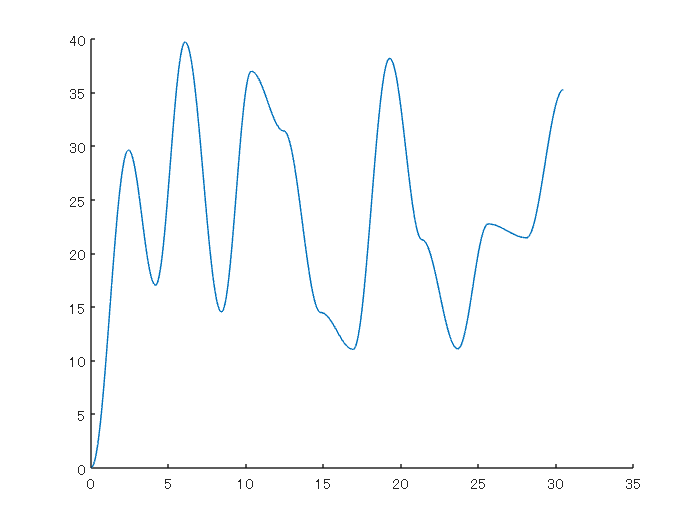

writetable(rightPedal, csvFolderName + '\' + "rightPedal.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
figure;
[rightPedal_x, rightPedal_t] = showGraph(clockTime, deltaTime, absolutePosition);

椅子　左　スライダ

clockTime = 0;
deltaTime = rand + randdt;
while clockTime(end,1) < clockTimeLimit - 2
    clockTime(end+1,1) = clockTime(end,1) + deltaTime(end,1);
    deltaTime(end+1,1) = rand + randdt;
end
absolutePosition = (seatSlideForwardLength + seatSlideBackwardLength) *rand(size(clockTime)) - seatSlideBackwardLength;
useStiffness = zeros(size(clockTime));

seatLeftSlider = table(clockTime, deltaTime, absolutePosition, useStiffness)

seatLeftSlider = 16×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

          0       1.7722           12.697              0      
     1.7722        2.337           61.758              0      
     4.1091       2.0272           57.474              0      
     6.1363       2.2849           42.421              0      
     8.4212       1.7323           88.081              0      
     10.153       1.8453           41.717              0      
     11.999         2.49          -47.213              0      
     14.489       1.8378           18.823              0      
     16.327        1.968           66.928              0      
     18.295       2.4317           3.1351              0      
     20.726       1.8449           12.795              0      
     22.571       1.6643          -21.286              0      
     24.235       1.8068           5.3056              0      
     26.042       1.5769  

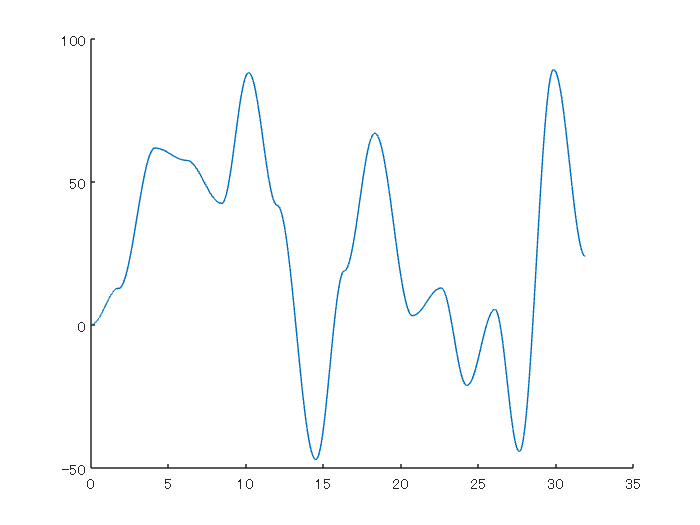

writetable(seatLeftSlider, csvFolderName + '\' + "seatLeftSlider.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
figure;
[seatLeftSlider_x, seatLeftSlider_t] = showGraph(clockTime, deltaTime, absolutePosition);

椅子　右　スライダ

clockTime = 0;
deltaTime = rand + randdt;
while clockTime(end,1) < clockTimeLimit - 2
    clockTime(end+1,1) = clockTime(end,1) + deltaTime(end,1);
    deltaTime(end+1,1) = rand + randdt;
end
absolutePosition = (seatSlideForwardLength + seatSlideBackwardLength) *rand(size(clockTime)) - seatSlideBackwardLength;
useStiffness = zeros(size(clockTime));

seatRightSlider = table(clockTime, deltaTime, absolutePosition, useStiffness)

seatRightSlider = 16×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

          0       2.0501           57.073              0      
     2.0501       1.8551             21.9              0      
     3.9051       2.1923           5.3303              0      
     6.0974       1.6702           36.524              0      
     7.7676       2.3804          -40.888              0      
     10.148       1.5688           55.938              0      
     11.717       1.9046           -8.674              0      
     13.621       2.0297           32.746              0      
     15.651        2.037           37.132              0      
     17.688       1.8138           78.592              0      
     19.502       1.7693           -39.44              0      
     21.271       2.2248           45.108              0      
     23.496       1.9168          -23.527              0      
     25.413       2.4366 

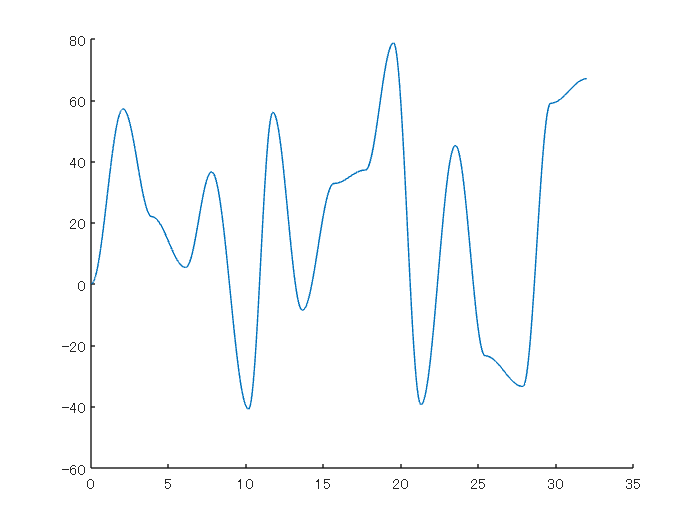

writetable(seatRightSlider, csvFolderName + '\' + "seatRightSlider.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
figure;
[seatRightSlider_x, seatRightSlider_t] = showGraph(clockTime, deltaTime, absolutePosition);

左ストックの伸縮　登山

L = extendLength; % スライド長 単位 (mm)
clockTime = 0;
deltaTime = rand + randdt;
while clockTime(end,1) < clockTimeLimit - 2
    clockTime(end+1,1) = clockTime(end,1) + deltaTime(end,1);
    deltaTime(end+1,1) = rand + randdt;
end
absolutePosition = L*rand(size(clockTime));
useStiffness = zeros(size(clockTime));

stockLeftExtend = table(clockTime, deltaTime, absolutePosition, useStiffness)

stockLeftExtend = 15×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

          0       2.0016           69.125              0      
     2.0016       1.6835           2.0692              0      
     3.6851        2.427           40.836              0      
     6.1121        1.794           87.772              0      
     7.9062        2.102           55.288              0      
     10.008       2.2952           13.865              0      
     12.303       2.1301           53.164              0      
     14.433       2.3095          0.82775              0      
     16.743       2.0973           17.054              0      
      18.84       2.1269           53.671              0      
     20.967       1.8716           65.035              0      
     22.839       2.2629           89.955              0      
     25.102       1.5785           97.837              0      
      26.68       2.3207 

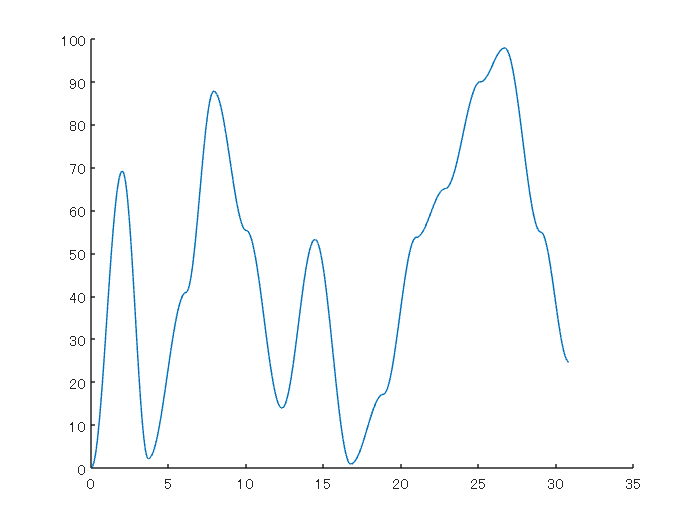

writetable(stockLeftExtend, csvFolderName + '\' + "stockLeftExtend.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
figure;
[stockLeftExtend_x, stockLeftExtend_t] = showGraph(clockTime, deltaTime, absolutePosition);

右ストックの伸縮　登山


L = extendLength; % スライド長 単位 (mm)
clockTime = 0;
deltaTime = rand + randdt;
while clockTime(end,1) < clockTimeLimit - 2
    clockTime(end+1,1) = clockTime(end,1) + deltaTime(end,1);
    deltaTime(end+1,1) = rand + randdt;
end
absolutePosition = L*rand(size(clockTime));
useStiffness = zeros(size(clockTime));

stockRightExtend = table(clockTime, deltaTime, absolutePosition, useStiffness)

stockRightExtend = 16×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

          0       1.7141           98.325              0      
     1.7141        1.945           33.134              0      
     3.6591       1.9955           74.863              0      
     5.6546       1.5836           61.658              0      
     7.2382       1.7322           74.806              0      
     8.9703       1.7151           98.247              0      
     10.685       2.4503           19.767              0      
     13.136       2.4846           42.948              0      
      15.62       1.6766           17.572              0      
     17.297       2.3156           73.693              0      
     19.613       1.5177           99.937              0      
      21.13       2.0783           28.269              0      
     23.209       1.8005           3.3054              0      
     25.009       2.1485

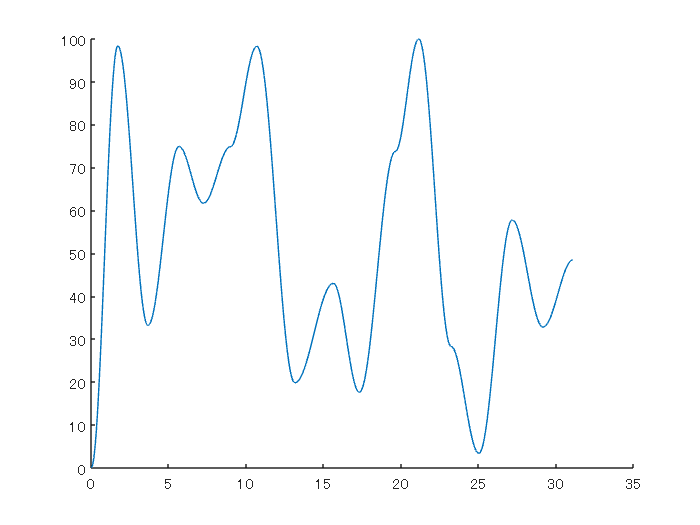

writetable(stockRightExtend, csvFolderName + '\' + "stockRightExtend.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition);
figure;
[stockRightExtend_x, stockRightExtend_t] = showGraph(clockTime, deltaTime, absolutePosition);

左ストックのスライダ

clockTime = 0;
deltaTime = rand + randdt;
while clockTime(end,1) < clockTimeLimit - 2
    clockTime(end+1,1) = clockTime(end,1) + deltaTime(end,1);
    deltaTime(end+1,1) = rand + randdt;
end
absolutePosition = (stockSlideForwardLength + stockSlideBackwardLength)*rand(size(clockTime)) - stockSlideBackwardLength;
useStiffness = zeros(size(clockTime));

stockLeftSlider = table(clockTime, deltaTime, absolutePosition, useStiffness)

stockLeftSlider = 15×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

          0       2.1667          -67.774              0      
     2.1667       1.7243          -42.591              0      
      3.891       1.6979           48.781              0      
     5.5889       2.0664          -92.606              0      
     7.6553       2.1953           82.146              0      
     9.8506       1.8989           29.671              0      
     11.749       2.3248          -82.641              0      
     14.074       1.9189           101.84              0      
     15.993       1.8359          -1.3416              0      
     17.829       1.9015           -4.782              0      
     19.731       2.2121          -75.599              0      
     21.943       2.3596           120.83              0      
     24.302       1.7922           122.08              0      
     26.094       2.4725 

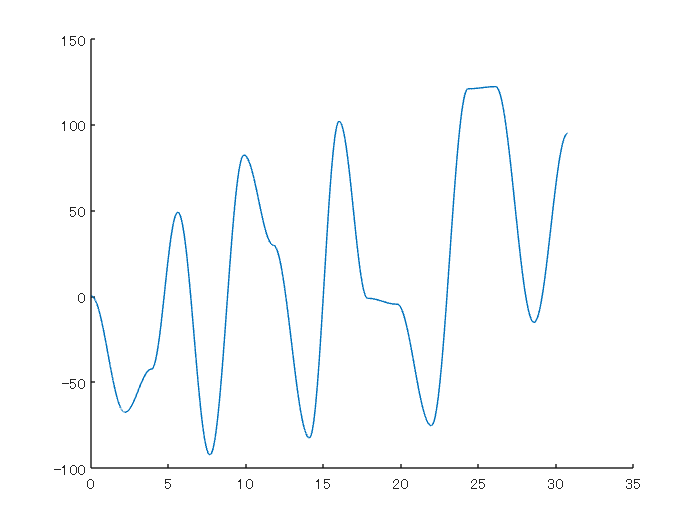

writetable(stockLeftSlider, csvFolderName + '\' + "stockLeftSlider.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition);
figure;
[stockLeftSlider_x, stockLeftSlider_t] = showGraph(clockTime, deltaTime, absolutePosition);

右ストックのスライダ

clockTime = 0;
deltaTime = rand + randdt;
while clockTime(end,1) < clockTimeLimit - 2
    clockTime(end+1,1) = clockTime(end,1) + deltaTime(end,1);
    deltaTime(end+1,1) = rand + randdt;
end
absolutePosition = (stockSlideForwardLength + stockSlideBackwardLength)*rand(size(clockTime)) - stockSlideBackwardLength;
useStiffness = zeros(size(clockTime));

stockLeftSlider = table(clockTime, deltaTime, absolutePosition, useStiffness)

stockLeftSlider = 16×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

          0       1.8813           80.522              0      
     1.8813       2.2196           -88.58              0      
     4.1009       1.9947          -72.952              0      
     6.0956       1.5122           1.2114              0      
     7.6078       1.7282            128.7              0      
      9.336       2.0546           33.124              0      
     11.391       2.3365          -59.434              0      
     13.727        1.548           57.037              0      
     15.275       1.6442           63.218              0      
     16.919       2.3339           106.73              0      
     19.253       2.3582          -36.226              0      
     21.612       1.6384          -60.944              0      
      23.25       1.8806           52.843              0      
      25.13       1.8569 


stockRightSlider = table(clockTime, deltaTime, absolutePosition, useStiffness)

stockRightSlider = 16×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

          0       1.8813           80.522              0      
     1.8813       2.2196           -88.58              0      
     4.1009       1.9947          -72.952              0      
     6.0956       1.5122           1.2114              0      
     7.6078       1.7282            128.7              0      
      9.336       2.0546           33.124              0      
     11.391       2.3365          -59.434              0      
     13.727        1.548           57.037              0      
     15.275       1.6442           63.218              0      
     16.919       2.3339           106.73              0      
     19.253       2.3582          -36.226              0      
     21.612       1.6384          -60.944              0      
      23.25       1.8806           52.843              0      
      25.13       1.8569

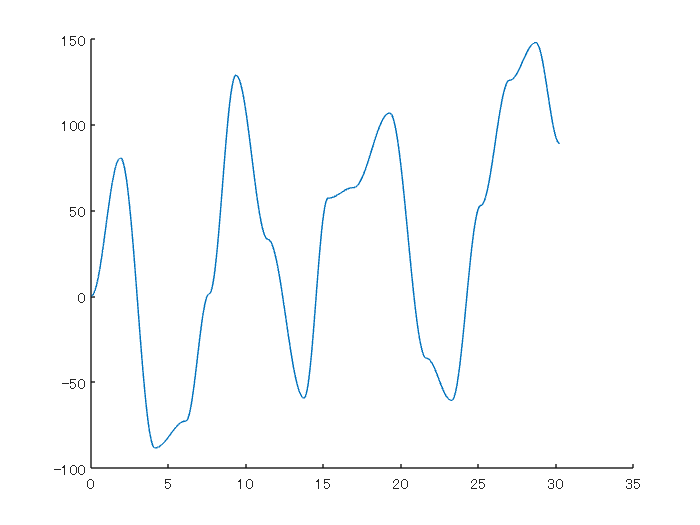

writetable(stockRightSlider, csvFolderName + '\' + "stockRightSlider.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition);
figure;
[stockRightSlider_x, stockRightSlider_t] = showGraph(clockTime, deltaTime, absolutePosition);

左ストック 前後傾

LF = tiltForwardDeg; % 単位 (deg)
LB = tiltBackwardDeg; % 単位 (deg)
startClockTimeLeftTilt = stockStartTime + period/2 + waitTime - period/8; % 開始時刻 (s)
clockTimeB = 0; % 単位 (s)
clockTimeF = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
leftTiltDeltaTimeB = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
leftTiltDeltaTimeF = period*stockBackwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
% leftTiltDelayTimeB = period*stockBackwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate) - leftTiltDeltaTimeF;
leftTiltDelayTimeB = 0;
leftTiltDelayTimeF = 0;
positionB = LB; % 単位 (deg)
positionF = LF; % 単位 (deg)

clockTimeBList = (startClockTimeLeftTilt + clockTimeB):period:clockTimeLimit; % 単位 (s)
clockTimeFList = (startClockTimeLeftTilt + clockTimeF):period:clockTimeLimit; % 単位 (s)
clockTimeBList = clockTimeBList(1:min([length(clockTimeFList), length(clockTimeBList)]));
clockTimeFList = clockTimeFList(1:min([length(clockTimeFList), length(clockTimeBList)]));
tmp = [clockTimeBList; clockTimeFList];
clockTime = tmp(:);
deltaTimeBList = leftTiltDeltaTimeB + 0*clockTimeBList;
deltaTimeFList = leftTiltDeltaTimeF + 0*clockTimeFList;
tmp = [deltaTimeBList; deltaTimeFList];
deltaTime = tmp(:);
positionBList = positionB + 0*clockTimeBList;
positionFList = positionF + 0*clockTimeFList;
tmp = [positionBList; positionFList];
absolutePosition = tmp(:);

% clockTime(end+1) = clockTimeLimit + period/2;
% deltaTime(end+1) = period/2;
% absolutePosition(end+1) = 0;

useStiffness = zeros(size(clockTime));

leftTilt = table(clockTime, deltaTime, absolutePosition, useStiffness)

leftTilt = 18×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

      2.625       1.2857              5                0      
     3.9107       1.7143            -10                0      
      5.625       1.2857              5                0      
     6.9107       1.7143            -10                0      
      8.625       1.2857              5                0      
     9.9107       1.7143            -10                0      
     11.625       1.2857              5                0      
     12.911       1.7143            -10                0      
     14.625       1.2857              5                0      
     15.911       1.7143            -10                0      
     17.625       1.2857              5                0      
     18.911       1.7143            -10                0      
     20.625       1.2857              5                0      
     21.911       1.7143        

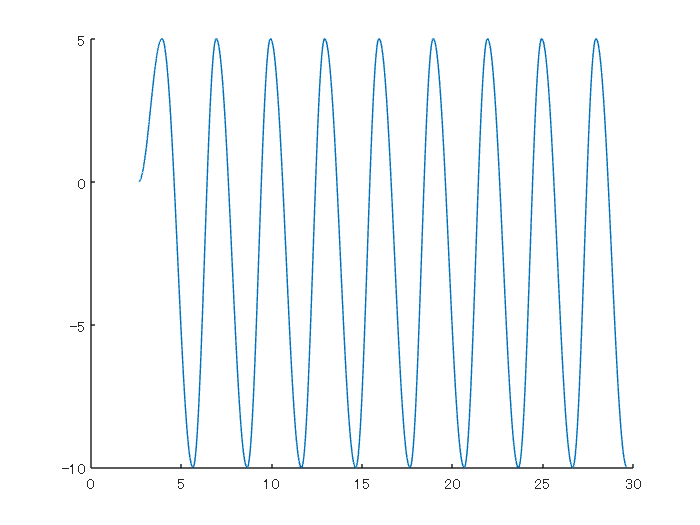

writetable(leftTilt, csvFolderName + '\' + "leftTilt.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition);
figure;
[leftTilt_x, leftTilt_t] = showGraph(clockTime, deltaTime, absolutePosition);

右ストック 前後傾

LF = tiltForwardDeg; % 単位 (deg)
LB = tiltBackwardDeg; % 単位 (deg)
startClockTimeRightTilt = stockStartTime + waitTime - period/8; % 開始時刻 (s)
clockTimeB = 0; % 単位 (s)
clockTimeF = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
rightTiltDeltaTimeB = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
rightTiltDeltaTimeF = period*stockBackwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
% rightTiltDelayTimeB = period*stockBackwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate) - rightTiltDeltaTimeF;
rightTiltDelayTimeB = 0;
rightTiltDelayTimeF = 0;
positionB = LB; % 単位 (deg)
positionF = LF; % 単位 (deg)

clockTimeBList = (startClockTimeRightTilt + clockTimeB):period:clockTimeLimit; % 単位 (s)
clockTimeFList = (startClockTimeRightTilt + clockTimeF):period:clockTimeLimit; % 単位 (s)
clockTimeBList = clockTimeBList(1:min([length(clockTimeFList), length(clockTimeBList)]));
clockTimeFList = clockTimeFList(1:min([length(clockTimeFList), length(clockTimeBList)]));
tmp = [clockTimeBList; clockTimeFList];
clockTime = tmp(:);
deltaTimeBList = rightTiltDeltaTimeB + 0*clockTimeBList;
deltaTimeFList = rightTiltDeltaTimeF + 0*clockTimeFList;
tmp = [deltaTimeBList; deltaTimeFList];
deltaTime = tmp(:);
positionBList = positionB + 0*clockTimeBList;
positionFList = positionF + 0*clockTimeFList;
tmp = [positionBList; positionFList];
absolutePosition = tmp(:);

% clockTime(end+1) = clockTimeLimit + period/2;
% deltaTime(end+1) = period/2;
% absolutePosition(end+1) = 0;

useStiffness = zeros(size(clockTime));

rightTilt = table(clockTime, deltaTime, absolutePosition, useStiffness)

rightTilt = 20×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

      1.125       1.2857              5                0      
     2.4107       1.7143            -10                0      
      4.125       1.2857              5                0      
     5.4107       1.7143            -10                0      
      7.125       1.2857              5                0      
     8.4107       1.7143            -10                0      
     10.125       1.2857              5                0      
     11.411       1.7143            -10                0      
     13.125       1.2857              5                0      
     14.411       1.7143            -10                0      
     16.125       1.2857              5                0      
     17.411       1.7143            -10                0      
     19.125       1.2857              5                0      
     20.411       1.7143       

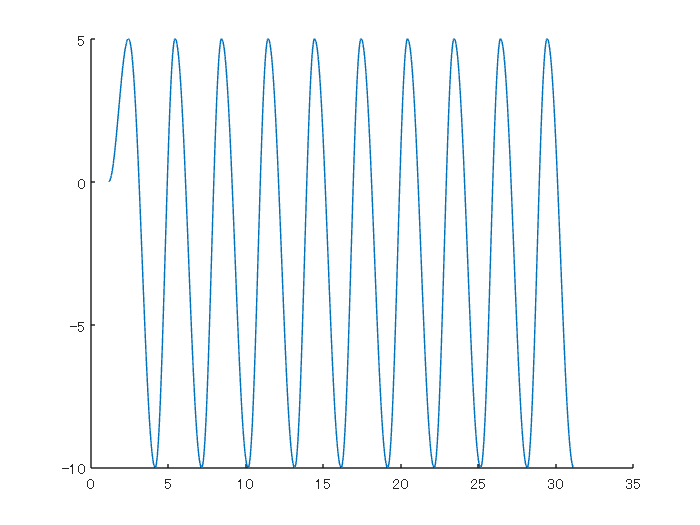

writetable(rightTilt, csvFolderName + '\' + "rightTilt.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition);
figure;
[rightTilt_x, rightTilt_t] = showGraph(clockTime, deltaTime, absolutePosition);

TiltCSV = table( ...
    period, tiltBackwardDeg, tiltForwardDeg, tiltBackwardTimeRate, tiltForwardTimeRate, startClockTimeLeftTilt, startClockTimeRightTilt, ...
    leftTiltDeltaTimeB, leftTiltDeltaTimeF, rightTiltDeltaTimeB, rightTiltDeltaTimeF, ...
    leftTiltDelayTimeB, leftTiltDelayTimeF, rightTiltDelayTimeB, rightTiltDelayTimeF ...
    )

TiltCSV = 1×15 table
    period    tiltBackwardDeg    tiltForwardDeg    tiltBackwardTimeRate    tiltForwardTimeRate    startClockTimeLeftTilt    startClockTimeRightTilt    leftTiltDeltaTimeB    leftTiltDeltaTimeF    rightTiltDeltaTimeB    rightTiltDeltaTimeF    leftTiltDelayTimeB    leftTiltDelayTimeF    rightTiltDelayTimeB    rightTiltDelayTimeF
    ______    _______________    ______________    ____________________    ___________________    ______________________    _______________________    __________________    __________________    ___________________    ___________________    __________________    __________________    ___________________    ___________________

      3              5                -10                   3                       4                     2.625                      1.125                   1.2857                1.7143                1.2857                 1.7143                   0                     0                      0                      0    

writetable(TiltCSV, csvFolderName + '\' + 'tilt.csv');

signal_lifter = timeseries(lifter_x, lifter_t, Name='lifter');
signal_leftPedal = timeseries(leftPedal_x, leftPedal_t, Name='leftPedal');
signal_rightPedal = timeseries(rightPedal_x, rightPedal_t, Name='rightPedal');
signal_seatLeftSlider = timeseries(seatLeftSlider_x, seatLeftSlider_t, Name='seatLeftSlider');
signal_seatRightSlider = timeseries(seatRightSlider_x, seatRightSlider_t, Name='seatRightSlider');
signal_stockLeftSlider = timeseries(stockLeftSlider_x, stockLeftSlider_t, Name='stockLeftSlider');
signal_stockRightSlider = timeseries(stockRightSlider_x, stockRightSlider_t, Name='stockRightSlider');
signal_stockLeftExtend = timeseries(stockLeftExtend_x, stockLeftExtend_t, Name='stockLeftExtend');
signal_stockRightExtend = timeseries(stockRightExtend_x, stockRightExtend_t, Name='stockRightExtend');
signal_leftTilt = timeseries(leftTilt_x, leftTilt_t, Name="leftTilt");
signal_rightTilt = timeseries(rightTilt_x, rightTilt_t, Name="rightTilt");

Scenario = Simulink.SimulationData.Dataset;

Scenario{1} = signal_lifter;
Scenario{2} = signal_leftPedal;
Scenario{3} = signal_rightPedal;
Scenario{4} = signal_seatLeftSlider;
Scenario{5} = signal_seatRightSlider;
Scenario{6} = signal_stockLeftExtend;
Scenario{7} = signal_stockRightExtend;
Scenario{8} = signal_stockLeftSlider;
Scenario{9} = signal_stockRightSlider;
Scenario{10} = signal_leftTilt;
Scenario{11} = signal_rightTilt;


% Scenario{2} = SignalStickRightPitch;
% Scenario{2}.Name = 'SignalStickRightPitch';
% Scenario{5} = signal_stockLeftPitch;
% Scenario{5}.Name = 'SignalStickLeftPitch';

save('../../../scenario.mat', 'Scenario');

sim("Simulink.slx");

clear;

function showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
    t = 0:0.001:deltaTime(1);
    x = absolutePosition(1)*(1 + cos(pi*t/deltaTime(1) + pi))/2;
    plot(t + clockTime(1), x);
    hold on;
    for idx = 2:length(clockTime)
        t = 0:0.01:deltaTime(idx);
        x = (absolutePosition(idx) - absolutePosition(idx-1)) * (1 + cos(pi*t/deltaTime(idx) + pi))/2 + absolutePosition(idx - 1);
        plot(t + clockTime(idx), x);
    end
end

function [ret_x, ret_t] = showGraph(clockTime, deltaTime, absolutePosition)
    % ret_t = [];
    t = (0:0.001:deltaTime(1))';
    x = absolutePosition(1)*(1 + cos(pi*t/deltaTime(1) + pi))/2;
    % plot(t + clockTime(1), x);
    ret_x = x;
    ret_t = t + clockTime(1);
    hold on;
    for idx = 2:length(clockTime)
        t = (0:0.01:deltaTime(idx))';
        x = (absolutePosition(idx) - absolutePosition(idx-1)) * (1 + cos(pi*t/deltaTime(idx) + pi))/2 + absolutePosition(idx - 1);
        % plot(t + clockTime(idx), x);
        ret_t = [ret_t; t + clockTime(idx)];
        ret_x = [ret_x; x];
    end
    plot(ret_t, ret_x);
end
